clear
syms x y z
assume(x,'real')
assume(y,'real')
assume(z,'real')

z = 5*x^3 + 3*y^4;

## Linearising

dzdx = diff(z,x);
dzdy = diff(z,y);
z_est_ksFunc = matlabFunction(z,dzdx,dzdy,'Vars',{x,y});

## Linearising at point

x0 = 0.6;
y0 = 0.4;
[z0,dzdx,dzdy] = z_est_ksFunc(x0, y0);

xs = linspace(-pi/4,pi/4,100);
ys = linspace(-pi/4,pi/4,100);
z_act_function = matlabFunction(z,'Vars',[x, y]);
zs_act = zeros(100);
zs_est1 = zeros(100);
for ix = 1:100
    for iy = 1:100
        xv = xs(ix);
        yv = ys(iy);
        zs_act(ix,iy) = z_act_function(xv, yv);
        zs_est1(ix,iy) = z0 + dzdx*(xv-x0) + dzdy*(yv-y0);
    end
end
figure(2), clf, hold on
mesh(xs, ys, zs_act,'EdgeColor','b','FaceAlpha',0,'FaceColor','b')
mesh(xs, ys, zs_est1,'EdgeColor','r','FaceAlpha',0,'FaceColor','r')
plot3(y0,x0,z0,'.k','MarkerSize',100)
view(3)

## Linearised Optimally

ks_init = [0 0];
% ks_init = [0 0 0];
f = @(ks) testKsEverywhere(ks, xs, ys, zs_act)

f = function_handle with value:
    @(ks)testKsEverywhere(ks,xs,ys,zs_act)


[ks_opt, err] = fminsearch(f, ks_init)

ks_opt =     1.6827    0.0000


err = 4.3101e+03

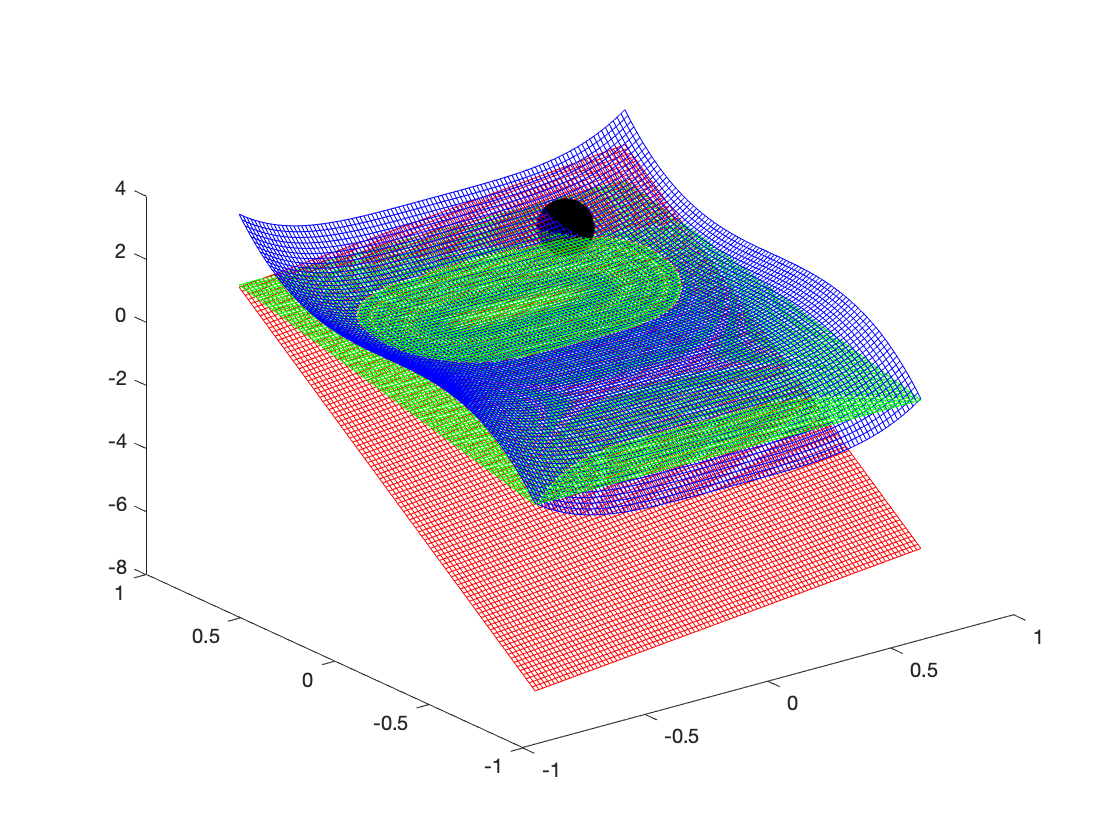


zs_est2 = zeros(100);
for ix = 1:100
    for iy = 1:100
        xv = xs(ix);
        yv = ys(iy);
        zs_est2(ix,iy) = ks_opt(1)*(xv) + ks_opt(2)*(yv);
%         zs_est2(ix,iy) = ks_opt(1)*(xv) + ks_opt(2)*(yv) + ks_opt(3);
    end
end
mesh(xs, ys, zs_est2,'EdgeColor','g','FaceAlpha',0,'FaceColor','r')

function err = testKsEverywhere(ks, xs, ys, zs_act)
    err = 0;
    for ix = 1:100
        for iy = 1:100
            xv = xs(ix);
            yv = ys(iy);
            z_est = ks(1)*xv + ks(2)*yv;
%             z_est = ks(1)*xv + ks(2)*yv + ks(3);
            err = err + abs(zs_act(ix,iy) - z_est);
        end
    end
end